% =====================================================================
% 测试信号分解模块的准确性（修正版）
% =====================================================================

clear; clc; close all;

%% 1. 生成测试信号
fs = 10000;
duration = 2;
t = (0:1/fs:duration-1/fs)';
linear_part = 1.0 * sin(2*pi*100*t);
nonlinear_part = 0.3 * sin(2*pi*200*t) + 0.15 * sin(2*pi*300*t) + 0.05*randn(size(t));
x_mixed = linear_part + nonlinear_part;

f0 = 100;       % 已知基频
delta_f = 15;   % 带宽 ±15Hz

%% 2. 分离（只调用一次，对整个信号）
[s_lin, s_nl] = separate_linear_nonlinear_by_freq(x_mixed, fs, f0, delta_f);

% 检查是否包含 NaN
if any(isnan(s_lin)) || any(isnan(s_nl))
    error('分离结果包含 NaN，请检查函数 separate_linear_nonlinear_by_freq');
end

%% 3. 评估分离结果
fprintf('=== 原始混合信号 ===\n');

=== 原始混合信号 ===


检测到基频: 100.10 Hz
THD: 0.3337 (33.37%)
峭度: 1.6141
最大滑动峭度: 1.8025

频段能量分布:
  [0-200 Hz]: 33.75%
  [200-500 Hz]: 14.27%
  [500-1000 Hz]: 5.68%

========== 综合评估 ==========
非线性综合评分: 0.538
评估等级: 中等非线性
控制策略建议: 建议神经网络主导控制，α 在 0.3~0.5


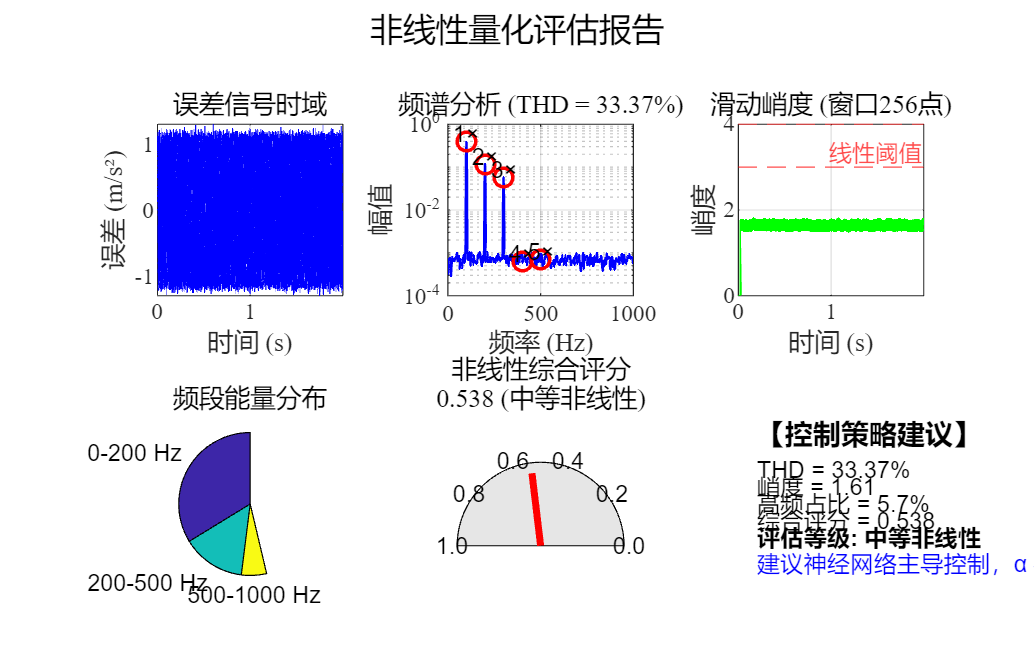

metrics_orig = nonlinear_quantification(x_mixed, fs);


fprintf('\n=== 分离后的线性分量 ===\n');


=== 分离后的线性分量 ===


检测到基频: 100.10 Hz
THD: 0.0002 (0.02%)
峭度: 1.5241
最大滑动峭度: 4.4016

频段能量分布:
  [0-200 Hz]: 98.08%
  [200-500 Hz]: 0.57%
  [500-1000 Hz]: 0.38%

========== 综合评估 ==========
非线性综合评分: 0.003
评估等级: 线性
控制策略建议: FxLMS 主导控制，无需神经网络补偿


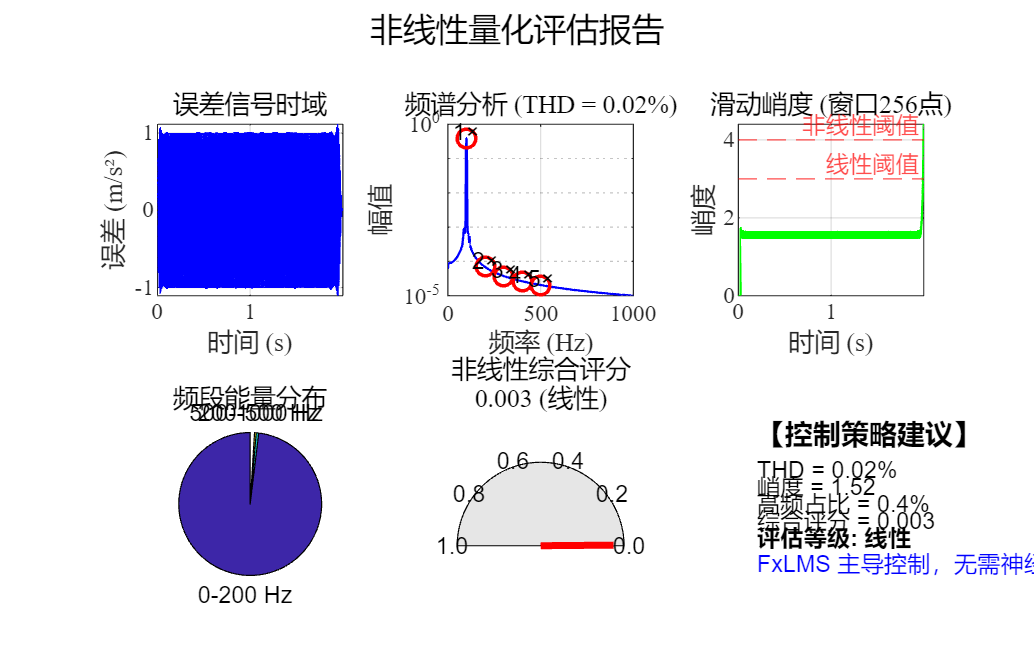

metrics_lin = nonlinear_quantification(s_lin, fs);


fprintf('\n=== 分离后的非线性分量 ===\n');


=== 分离后的非线性分量 ===


检测到基频: 200.20 Hz
THD: 0.0192 (1.92%)
峭度: 2.8477
最大滑动峭度: 3.0342

频段能量分布:
  [0-200 Hz]: 6.20%
  [200-500 Hz]: 20.19%
  [500-1000 Hz]: 8.05%

========== 综合评估 ==========
非线性综合评分: 0.054
评估等级: 线性
控制策略建议: FxLMS 主导控制，无需神经网络补偿


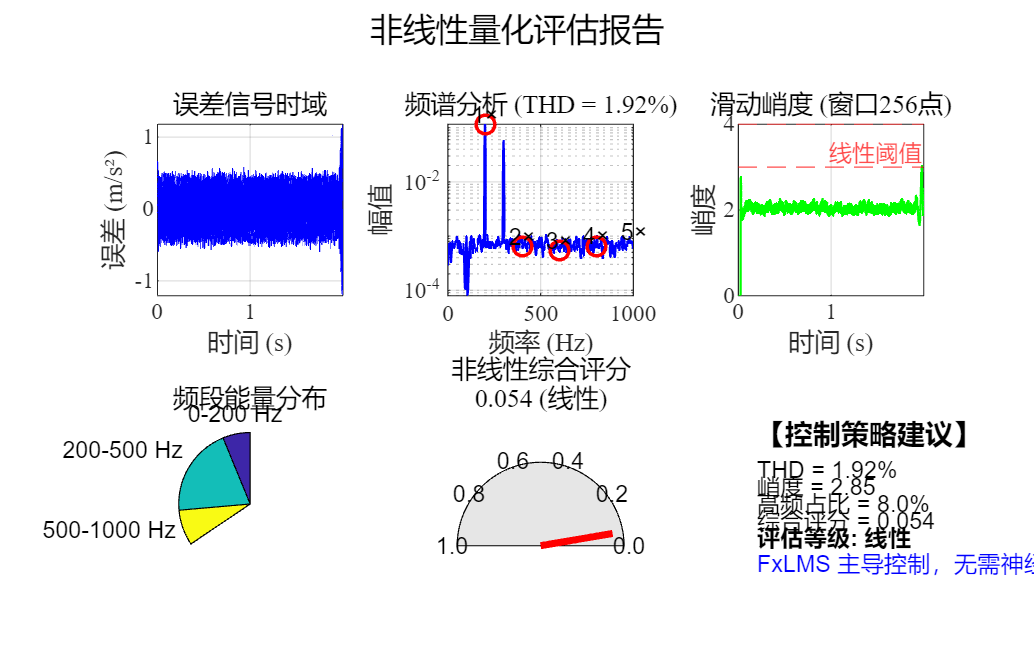

metrics_nl = nonlinear_quantification(s_nl, fs);

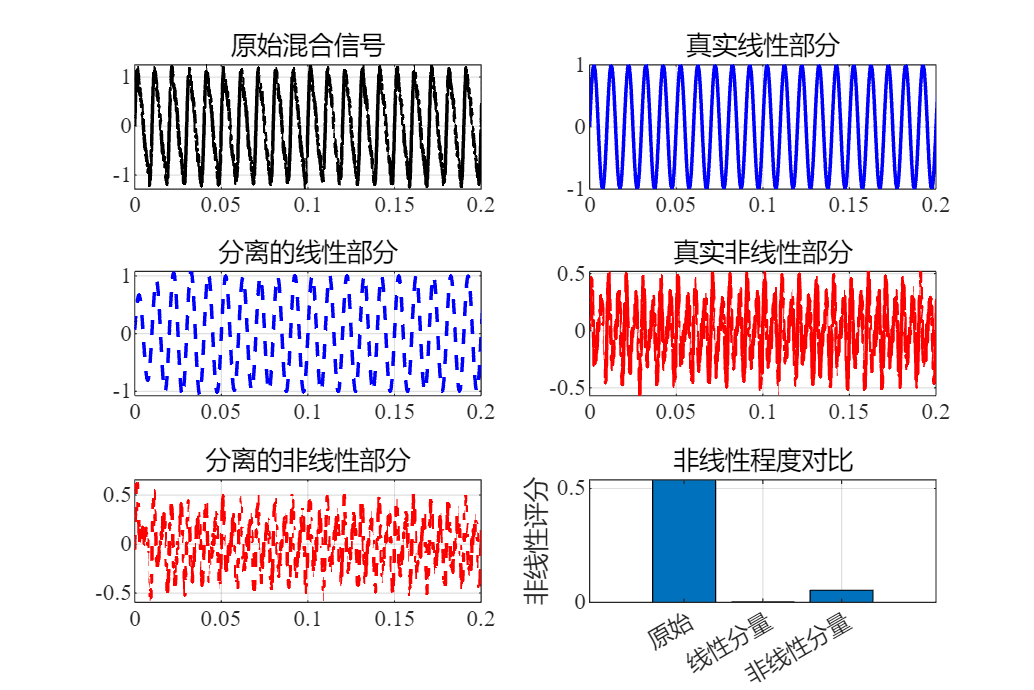


%% 4. 绘图
figure('Name', '信号分解效果', 'Position', [100,100,1200,800]);

subplot(3,2,1);
plot(t, x_mixed, 'k'); title('原始混合信号'); xlim([0,0.2]); grid on;
subplot(3,2,2);
plot(t, linear_part, 'b'); title('真实线性部分'); xlim([0,0.2]); grid on;
subplot(3,2,3);
plot(t, s_lin, 'b--'); title('分离的线性部分'); xlim([0,0.2]); grid on;
subplot(3,2,4);
plot(t, nonlinear_part, 'r'); title('真实非线性部分'); xlim([0,0.2]); grid on;
subplot(3,2,5);
plot(t, s_nl, 'r--'); title('分离的非线性部分'); xlim([0,0.2]); grid on;
subplot(3,2,6);
bar([metrics_orig.nonlinear_score, metrics_lin.nonlinear_score, metrics_nl.nonlinear_score]);
set(gca, 'XTickLabel', {'原始','线性分量','非线性分量'});
ylabel('非线性评分'); title('非线性程度对比');
grid on;


%% 5. 量化对比表格
fprintf('\n========== 量化对比 ==========\n');


========== 量化对比 ==========


fprintf('指标              原始信号    线性分量    非线性分量\n');

指标              原始信号    线性分量    非线性分量


fprintf('THD (%%%)          %.2f        %.2f        %.2f\n', ...
    metrics_orig.thd*100, metrics_lin.thd*100, metrics_nl.thd*100);

THD (%

fprintf('峭度               %.2f        %.2f        %.2f\n', ...
    metrics_orig.kurtosis, metrics_lin.kurtosis, metrics_nl.kurtosis);

峭度               1.61        1.52        2.85


fprintf('非线性评分         %.3f        %.3f        %.3f\n', ...
    metrics_orig.nonlinear_score, metrics_lin.nonlinear_score, metrics_nl.nonlinear_score);

非线性评分         0.538        0.003        0.054
